**AIM:**The aim is to design and implement a self-interference cancellation in systems where simultaneously message it transmitted and received by a system. The transmission channel is same as the receiving channel so the transmitted signal interferes with the received signal. Then we recover the actual received signal from the signal generated by interference. To make things simpler  the message transmitted will directly be also getting added to the received signal with same amplitude and some time delay. Here as input signal we take a recorded voice signals. The recovered signal shall be the origional signal being recieved.

**Adaptive Noise removal idea:**

This usually involves recording the signal from **multiple sources** and **complex algorithms** which **predict the approximation of noise added** which is then subtracted from the recieved signal to get the origional signal approximately. In this project we stick with the transmitted signal being noise as any other noise will make the project a lot more complex to complete within given time.

**SETUP**:IN  the module 1 we have showed the basic implementation of removing the known interfering transmitted signal from the unknown recieving signal. The recieved signal is a sum of both transmitted and recieved signals.We initially directly added the transmitted signal to recieved signal to explain the working . In later part to make the stimulation resemble real world system we take a gap of 1000 samples before transmitted signal will get added to the recieving signal stimulating a normal antenna which will have some time lag in generated and recieved signals.

But in this case the time lag needs to be known before hand to properly eliminated the interfering transmitted signal from the actual recieved signal otherwise for any unknown time /sample delay this system will not be very accurate.

**Additions from module1:**

- Better comments and some added texts to improve understanding. Removed redundant codes and plots (the first part which were repeting again in second part would not happen in any real world case.).

- Better plots to see the difference in actual, corrupted and recovered signals which looked roughly the same in module 1 (when the difference could only be found by listening). Now we can spot the difference even from frequency domain plots(**Especially by looking at the amplitude**).

**Instructions:**

- I have used 2 recorded signals in this lab and they are labled Transmitted.wav(Contains the signal being transmitted by the antenna in out stimulation) and Recieving.wav(Contains the signal being recieved by our atenna simultaneously).

- We have kept the signals between 2-3 secs for fast implementation. And all sounds will be played starting from 1)transmitted signal (line11) ; 2)recieving signal(line14) ; 3)Recieved signal with NOISE(line 63) ; 4)recovered signal after frequency domain filtering /computations(line 84).

- To listen to a particular signal you can copy the sound command for that signal to command window or comment all other sounds in the code.

- I have plotted time domain and frequency domain plots for all signals and can be used to visualize what is actually hapenning .

- Some variables are used again so if their values in between of code is required it will be necessary to use breakpoints.

%CODE STARTS

%%Uncomment to clear clear all existing data which is not really necessary in notebook as graphs don't usually pop out..
% clc;  %clear command window
% clear all;  %clear our workspace
% close all;  %closes all other workable windows

## Reading the recorded message signal signals

%We need to read the sampling frequency too otherwise might loose accuracy
[transmitted,fts]=audioread('Transmitted_noise.wav');  %Reading the transmitted signal which will be used as (NOISE sigal)
ts=1/fts; % sampling time ie. 1/sampling frequency of transmitted signal
[recieving,frc]=audioread('Recieving .wav'); %Reading the recieved signal

The origional signal being transmitted: Will act as NOISE

trc=1/frc; % sampling time ie. 1/sampling frequency of recieved signal

Sound of the transmitted and to be recieved signals

fprintf("The origional signal being transmitted: Will act as NOISE")

The origional signal being recieved: (Without noise)

sound(transmitted,fts) %To play the transmitted sigal sound
pause(4); %This pausing is needed to listen to both seperately
fprintf("The origional signal being recieved: (Without noise)")
sound(recieving,frc);pause(1);   %To play the signal which will be recieved and waiting a sec

We then convert the signals to frequency domain using fft to make joining them easier.

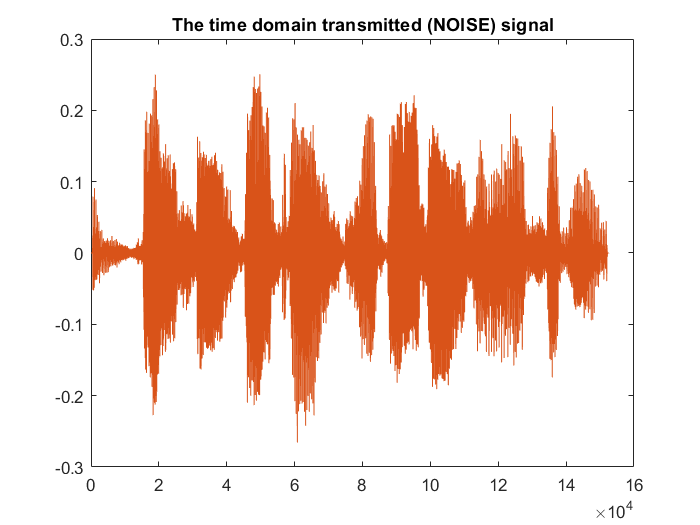

%% To take fft of tramsmitted signal
L = length(transmitted);
NFFTt = 2^nextpow2(L); % Next power of 2 from length of transmitted
Y = fft(transmitted,NFFTt)/L; %We take NFFTt point fft of transmitted signal and store in Y
ft = fts/2*linspace(0,1,NFFTt/2+1); %To get the frequency axis points

%%To take fft of the original signal which shall be recieved
L = length(recieving);
NFFTr = 2^nextpow2(L); % Next power of 2 from length of recieving
X = fft(recieving,NFFTr)/L; %We take NFFTr point fft of recieving signal and store in X 
fr = frc/2*linspace(0,1,NFFTr/2+1); %To get frequency points.

Plotting the Input signals in time and frequency domains

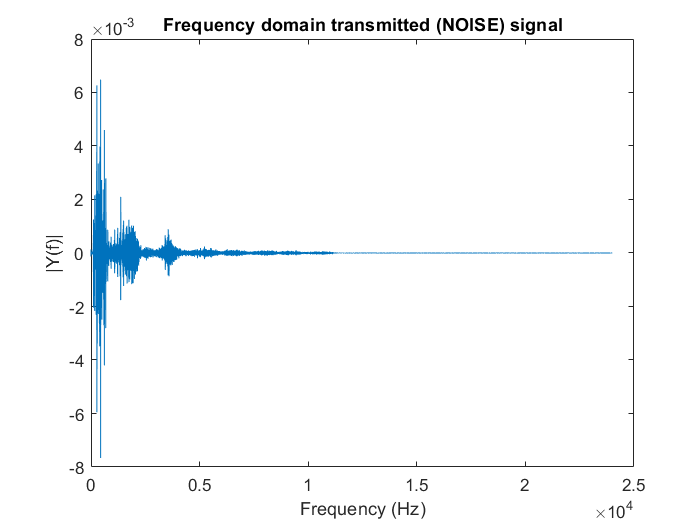

%Plotting transmitted signal
plot(transmitted)
title("The time domain transmitted (NOISE) signal")
% Plot single-sided amplitude spectrum of transmitted signal.
plot(ft,2*real(Y(1:NFFTt/2+1)))

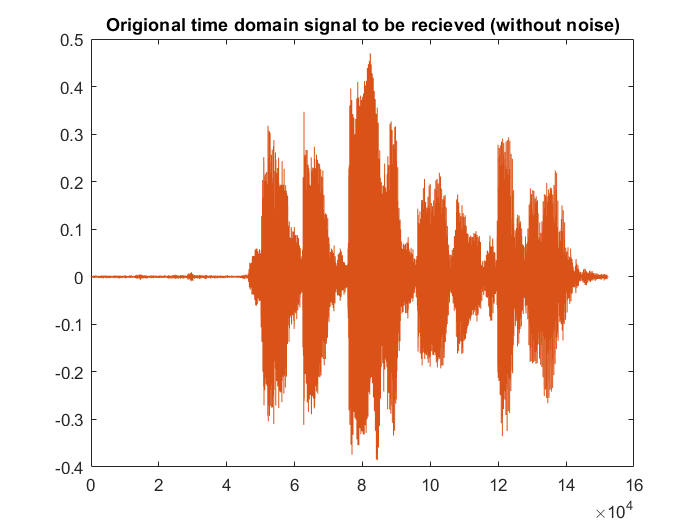

title('Frequency domain transmitted (NOISE) signal')
xlabel('Frequency (Hz)')
ylabel('|Y(f)|')


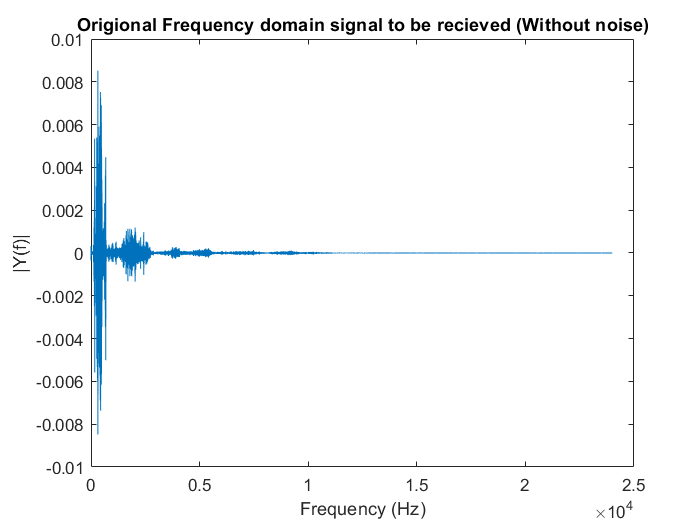

%Plotting recieving(original signal which shall be recieved) signal.
plot(recieving)
title("Origional time domain signal to be recieved (without noise)")
plot(fr,2*real(X(1:NFFTr/2+1)))

title('Origional Frequency domain signal to be recieved (Without noise)')
xlabel('Frequency (Hz)')
ylabel('|Y(f)|')


Real world stimulation with delayed transmitted signal(NOISE)
 getting added to recieved signal ---


Clearly in the frequency domain plots we can see that the frequency magnitude of transmitted(NOISE) signal and to be recieved signal are different.

**Next we add the known transmitted signal with some known time gap to stimulate real world situation.**

This time we add the delayed transmitted(by 1000 samples) and recieving signals in frequency domain to get the simple recieved signal.And then convert the recieved signal back to time domain 

fprintf("\nReal world stimulation with delayed transmitted signal(NOISE)\n getting added to recieved signal ---\n")
D=1000; %We delay the transmitted signal by 1000 samples before adding to recieved to get the actual recieved signal.
delay = dsp.Delay(D);%To make function to delay input by 1000 samples
delayedT=delay(transmitted); %To generate the delayed version of transmitted signal being delayed by D samples.

%Next we convert the delayed signal to frequency domain
L = length(delayedT);
NFFTt = 2^nextpow2(L); % Next power of 2 from length of transmitted
delayedY= fft(delayedT,NFFTt)/L; %We take NFFTt point fft of transmitted signal and store in Y
ft = fts/2*linspace(0,1,NFFTt/2+1); %To get the frequency axis points
recievedf=delayedY+ X;  %In frequency domain actually recieved signal using delayed signal

recieved = ifft(recievedf,NFFTr)*L; %The actually recieved signal in time domain(Interfered)

The signal recieved after adding NOISE (Delayed transmitted signal)
 It resembles transmitted/NOISE signal more than the recieving signal

Plotting the interfered signal which is obtained by directly adding the delayed transmitted signal(**noise)** to the recieved signal .

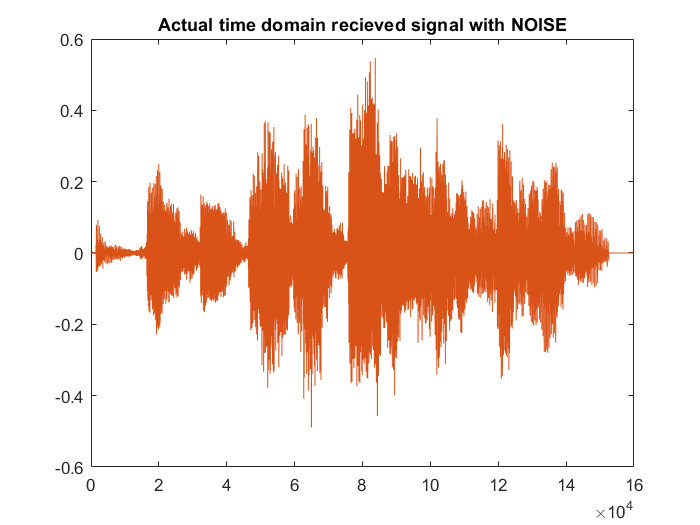

fprintf("The signal recieved after adding NOISE (Delayed transmitted signal)\n It resembles transmitted/NOISE signal more than the recieving signal")
plot(recieved) %Plots the time domain plot of corrupted signal (corrupted with NOISE ie. transmitted signal).

title("Actual time domain recieved signal with NOISE")
xlim([0 16*10^4])
plot(fr,2*real(recievedf(1:NFFTr/2+1))) %Plots the frequency domain plot of corrupted signal
title('Frequency domain plot of actual recieved signal (with NOISE)')
xlabel('Frequency (Hz)')
ylabel('|Y(f)|')

Sound of the actually recieved signal

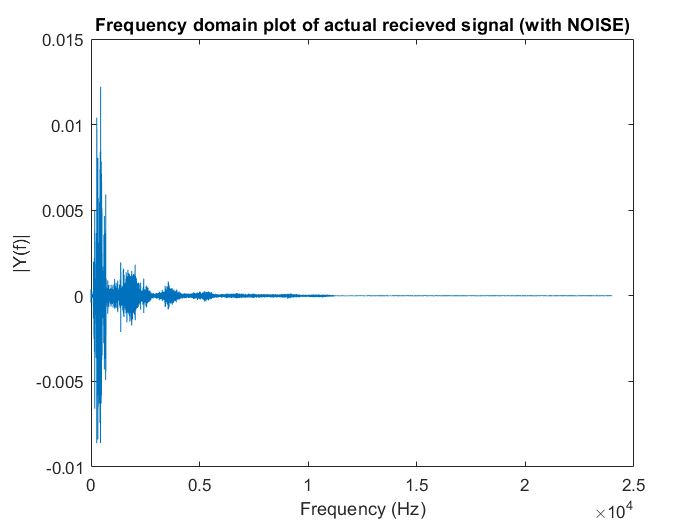

sound(real(recieved),frc) %We can listen to the actual recieved signal after adding transmitted signal as noise. 

                               % We can hear two audios the other one being noise.
pause(3)% We can feel that it contains two sounds.

**NOTE** :This can also occur if two signals are played together(with some delay in one of them) and we have to get the individual signals from that mixture.

Our aim is to seperate the origional recieved signal by knowing the transmitted signal which is interfering with it with the delay with which its added to recieved signal.

WE use the frequency scaling of fft to counter/Cancel the effect of time shifted noise.

Now a delay of D samples in time domain will scale its fft by $e^{\frac{-j2 \pi k D}{N}}$. So while recovering we can use the transmitted signal scaled by $e^{\frac{-j2 \pi k D}{N}}$ where k denotes the term of fft starting from 0 to NFFTr-1..ie.$yscaled
=  \sum_{k=0}^{L_h-1}e^{\frac{-j2 \pi k D}{N}}Y[k]$ 

and subtract it with the recieved signal to remove its effect and thus recover the signal.

%We know the transmitted signal(NOISE) at the antenna and the actual recieved
%signal to recover the origional signal by removing the effect of NOISE.
Yscaled=Y;   %We initialize it with y
for k=0:length(Y)-1
Yscaled(k+1,:)=(exp(-2*i*pi*k*D/NFFTr)*Y(k+1,:));  %In the expression we only see 1 k but since array indexes have to be positive we add 1.
end  % this gives the scaled version of transmitted signal which will cancel the effect of it.

recoveredf=recievedf- Yscaled; %Here we sybtract the scaled version of Y to deal with phase lag to get the recovered signal

This will work till we know the samples the transmitted signal(NOISE) is being **delayed **before getting added to recieving signal (Corrupting it). For a fixed but unknown delay we can do some trail and error and get the best value but then this process will not be very acurate.

We convert the frequency domain recovered signal back to time domain.

%%We take ifft of the recovered signal to get time domain recovered signal
recovered = ifft(recoveredf,NFFTr)*L; %The recovered signal in time domain

The recovered signal

To plot the delayed inteferance recovered signal

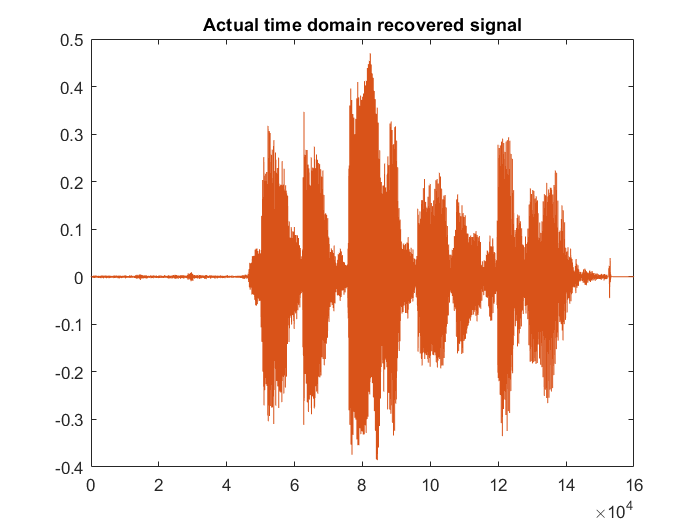

fprintf("The recovered signal")
plot(real(recovered)); %The recovered signal is complex but we need the real part

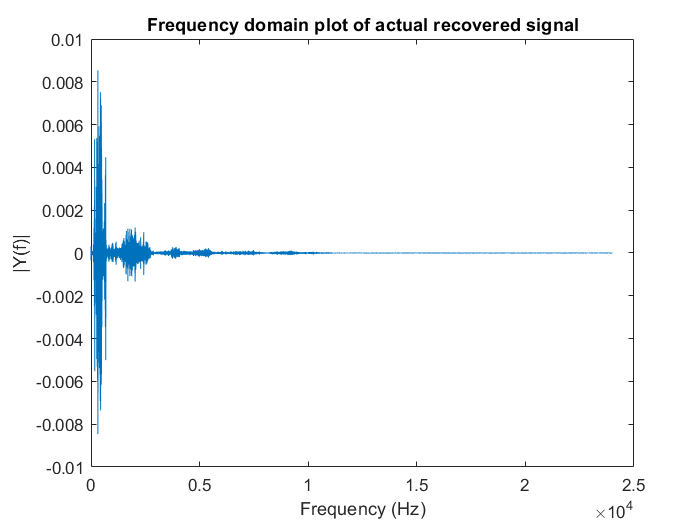

xlim([0 16*10^4])
title("Actual time domain recovered signal")
plot(fr,2*real(recoveredf(1:NFFTr/2+1))) %Plotting frequency domain recovered signal
title('Frequency domain plot of actual recovered signal')

xlabel('Frequency (Hz)')
ylabel('|Y(f)|')

To listen to the recovered signal

sound(real(recovered),frc); %plays the recovered signal "This is the recieving signal" in this case.